load tupleCount-R71-M0-N4-BGLErrorLog.txt

load tupleCount-R12-M0-N0-BGLErrorLog.txt

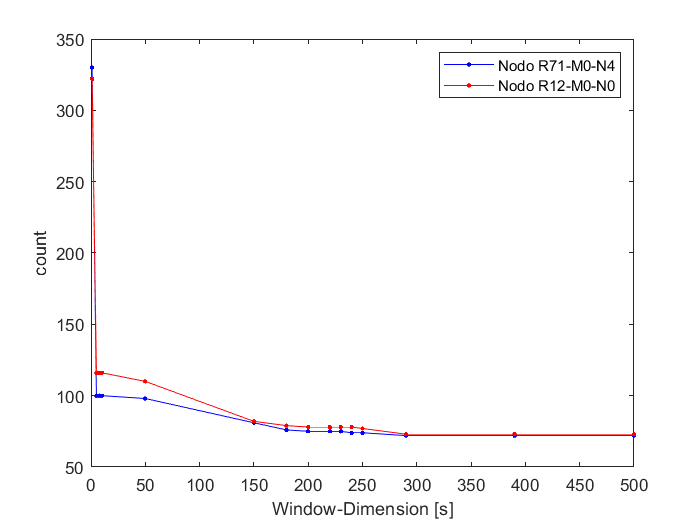

plot(r71(:,1), r71(:,2), '.-b', r12(:,1), r12(:,2), '.-r');
% ,s044(:,1), s044(:,2), '.-r'
xlabel('Window-Dimension [s]');
legend('Nodo R71-M0-N4', 'Nodo R12-M0-N0')
ylabel('count');

load tupling_R12-M0-N0-BGLErrorLog-50\interarrivals.txt

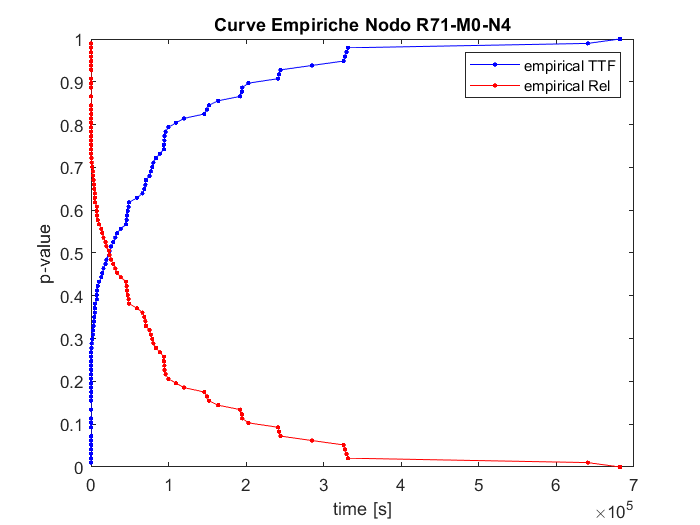

[y71,t71] = cdfcalc(interarrivals71);
empTTF71=y71(2:size(y71,1));
empRel71=1-empTTF71;
plot(t71,empTTF71,'.-b',t71,empRel71,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Nodo R71-M0-N4')
legend('empirical TTF', 'empirical Rel');

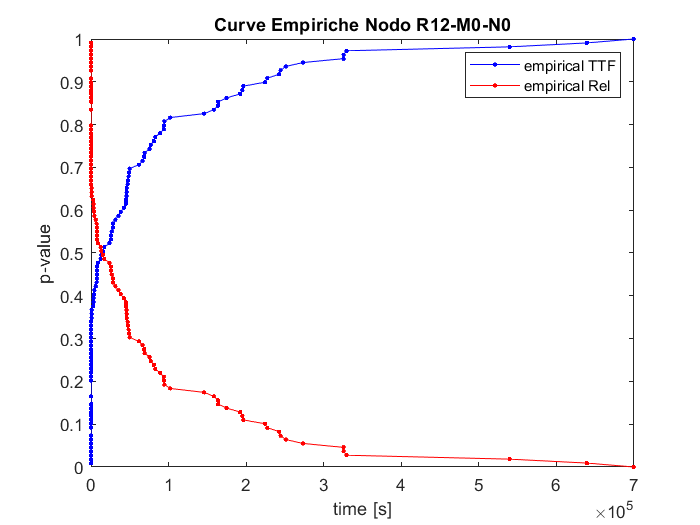

[y12,t12] = cdfcalc(interarrivals12);
empTTF12=y12(2:size(y12,1));
empRel12=1-empTTF12;
plot(t12,empTTF12,'.-b',t12,empRel12,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Nodo R12-M0-N0')
legend('empirical TTF', 'empirical Rel');

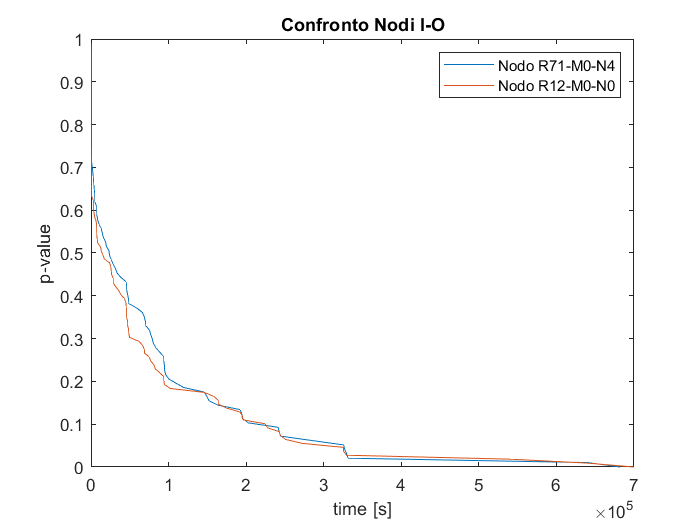

plot(t71,empRel71,t12,empRel12)
xlabel('time [s]'); ylabel('p-value'); title('Confronto Nodi I-O')
legend('Nodo R71-M0-N4', 'Nodo R12-M0-N0');

load tupleCount-R63-M0-N2-BGLErrorLog.txt

load tupleCount-R03-M1-NF-BGLErrorLog.txt

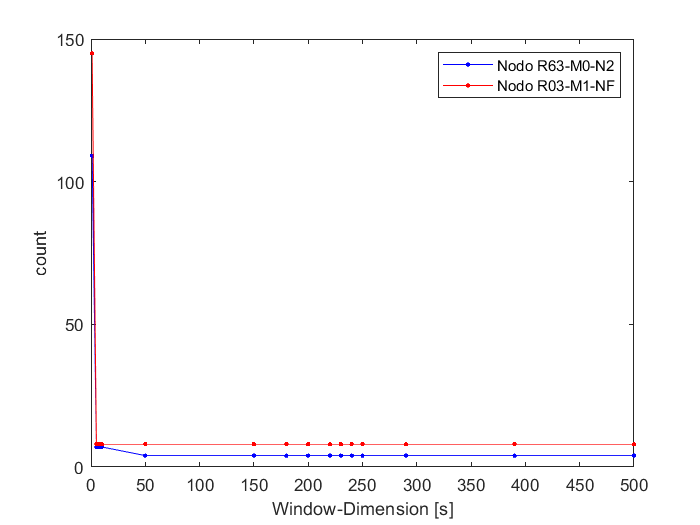

plot(r63(:,1), r63(:,2), '.-b', r03(:,1), r03(:,2), '.-r');
xlabel('Window-Dimension [s]');
legend('Nodo R63-M0-N2', 'Nodo R03-M1-NF')
ylabel('count');

load tupling_R63-M0-N2-BGLErrorLog-8\interarrivals.txt

load tupling_R03-M1-NF-BGLErrorLog-8\interarrivals.txt

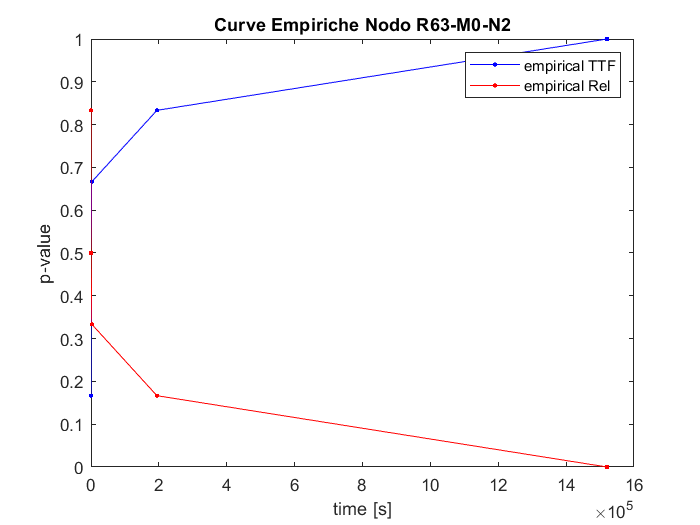

[y63,t63] = cdfcalc(interarrivals63);
empTTF63=y63(2:size(y63,1));
empRel63=1-empTTF63;
plot(t63,empTTF63,'.-b',t63,empRel63,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Nodo R63-M0-N2')
legend('empirical TTF', 'empirical Rel');

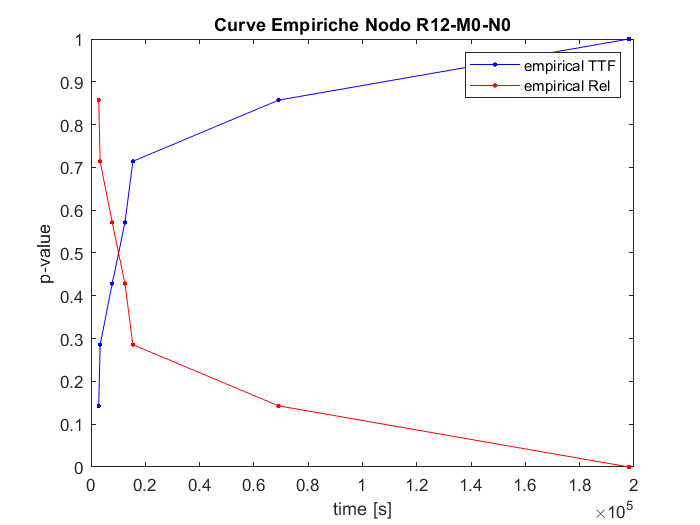

[y03,t03] = cdfcalc(interarrivals03);
empTTF03=y03(2:size(y03,1));
empRel03=1-empTTF03;
plot(t03,empTTF03,'.-b',t03,empRel03,'.-r');
xlabel('time [s]'); ylabel('p-value'); title('Curve Empiriche Nodo R12-M0-N0')
legend('empirical TTF', 'empirical Rel');

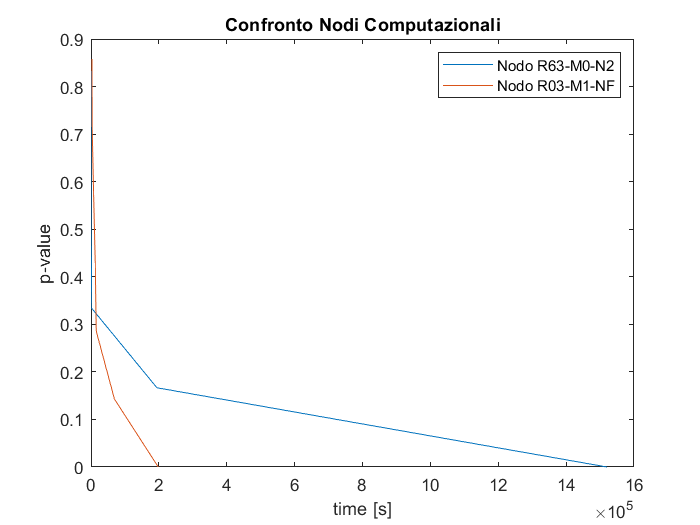

plot(t63, empRel63, t03,empRel03);
xlabel('time [s]'); ylabel('p-value'); title('Confronto Nodi Computazionali')
legend('Nodo R63-M0-N2', 'Nodo R03-M1-NF')